# Numerical Frequency Test

This live-script features the following:

- 2D example

- construct acoustic sources via functions

- setup to run basic acoustic solver

- different visualizations

- plot for medium parameters

- animate for solutions

- animateMedBack for solutions

- plotTimeSeries for solutions

Acoustic equations: 


$$\frac{\partial p}{\partial t} + \kappa \left( \frac{\partial v_x}{\partial x}  + \frac{\partial v_y}{\partial y}\right)= f_p$$



$$\frac{\partial v_x}{\partial t} + \beta \frac{\partial p}{\partial x} = f_{v_x}$$



$$\frac{\partial v_y}{\partial t} + \beta \frac{\partial p}{\partial y} = f_{v_y}$$


assuming zero-pressure at boundaries, and initial conditions provided by user.

## Week 6-7 implementations:

- Includes square grid, $ h = \Delta x = \Delta y$, where h is the grid spacing between each point.

h is computed to satisfy a desired range of points per wavelength. 

The computational spatial grid is defined and used to initialize the grid space for the pressure fields.

clear

%clean code

N_lambda = 20; %desired points per wavelength

CFL_factor = 0.8;

% medium = AcousticMedium2D.constant(KappaValue=1,BetaValue=1);
kappa_val = 1;
beta_val = 1;
c = sqrt(kappa_val*beta_val);

%Length of grid space for choice of square grid, change to L maybe?
Lx = 1;
Ly = Lx;
Lt = 1;
%make sure time is ten periods 
domain_x = [0,Lx];
domain_y = [0,Ly];


m = 1; %calculates angular frequency
n = 1;

kx = m*pi/Lx;
ky = n*pi/Ly;
K = sqrt(kx^2 + ky^2);
h_init = 2*pi/(N_lambda*K);

%grid spacing for a square grid
Nx = ceil(Lx/h_init)+1; %use ceiling to solve for integers
Ny = Nx;
h = Lx/(Nx-1);
dx = Lx;


%originally had this, but an error regarding the 2D solver mentioned dt
%being too large to remain stable
%dt = CFL_factor*(h/c)*((6/7)*(1/sqrt(2));

%used in finding discrete dispersion rel
N_lambda_recomp = 2*pi/(h*K)

N_lambda_recomp = 21.2132

%NEW STUFF
theta = atan(ky/kx);
fprintf('Wave-vector angle: %.2f degrees\n',theta*180/pi);

Wave-vector angle: 45.00 degrees


%generates x and y mesh points
grid_x_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_y_primal = Grid1DUnifPrimal(domain_y,Ny);
gsp_P = GridSpace2D(grid_x_primal,grid_y_primal);

[x_mesh,y_mesh] = gsp_P.mesh();
% Acoustic medium parameters 

medium = AcousticMedium2D.constant( ...
   "KappaValue",kappa_val,"BetaValue",beta_val);

% After creating gsp_P and sampling the medium
[kappa,betaX,betaY,wavespeed,cMax] = sampleMedium2D(gsp_P,medium);

Unlike the spatial grid, we store the temporal grid as a simple array of time points.

For the 2-4 staggered FD scheme in 2D, we take $\Delta_t$ such that 

$\Delta_t \le \frac{6}{7} \left( c_{\rm max} \sqrt{ \frac{1}{\Delta_x^2} + \frac{1}{\Delta_y^2} } \right)^{-1}$.

When computing $\Delta_t$, it is important to ensure that the computational time interval is divisible by the step-size. Usually this requires a recomputation of $\Delta_t$ as done so here.

% Compute a stable, fixed time step
dt = CFL_factor*(6/7)/(cMax*sqrt(sum(1./gsp_P.h.^2)));

% calculate the predicted frequency using this dt
F_22 = sqrt(sin(kx*h/2)^2 + sin(ky*h/2)^2);
gamma = c*(dt/h);
omega_pred = (2/dt)*asin(gamma*F_22);
omega_exact = c*K;

% Choose the simulation duration
num_periods = 10;
T = 2*pi/omega_pred;
t_final = num_periods*T;

% Create time points without changing dt
Nt = ceil(t_final/dt) + 1;
t_pts = (0:Nt-1)*dt;

Here we specify the initial conditions functions such that


$$p(x,y,0) = $$



$$v_x(x,y,0) = v_{x,0}(x,y)$$



$$v_y(x,y,0) = v_{y,0}(x,y)$$


% Initial data
p0 = @(x,y) sin(kx*x).*sin(ky*y);
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

Before running the solver, we must initialize it using the computational grid space and time points, output grid space and time points, and medium parameters.

% Initializing solver
solver = AcousticSolver2DStaggered( ...
    gsp_P,t_pts,...
    gsp_P,t_pts,...
    medium, ...
    SpatialOrder=2);

To run the solver, we make use of the `solve()` method, and input the initial conditions, along with the acoustic source.

The outputs/solutions are of type `GridFunctionTimeSeries`.

% Run the solver
[P,Vx,Vy] = solver.solve(p0,vx0,vy0);

## Extracting Modal Amplitude

how strongly the pressure field matches the standing wave

phi = sin(kx*x_mesh) .* sin(ky*y_mesh); 
phiNormSq = sum(phi.^2,"all");

class(sin(kx*x_mesh));
class(sin(ky*y_mesh));
size(x_mesh);
size(y_mesh);
a = zeros(Nt,1);
for it = 1:Nt
pNow = P.values(:,:,it);
a(it) = sum(pNow .* phi,"all") / phiNormSq;
end

%it will blow up when pressure field is 0
modalResidual = zeros(Nt,1);
for it = 1:Nt
pNow = P.values(:,:,it);
pMode = a(it)*phi;
modalResidual(it) = norm(pNow(:)-pMode(:)) / norm(pNow(:));
end


Fitting

fit = fitModalFrequency(t_pts,a,omega_pred);

 
 Func-count     x          f(x)         Procedure
    1        4.22901      125.305        initial
    2        4.64813      116.704        golden
    3        4.90717      219.256        golden
    4        4.45528      1.00348        parabolic
    5        4.44232    0.0506873        parabolic
    6        4.43444     0.062116        parabolic
    7        4.43858  9.69301e-08        parabolic
    8        4.43858  4.12794e-08        parabolic
    9        4.43857  1.97674e-13        parabolic
   10        4.43857  1.25189e-11        parabolic
   11        4.43857  1.96021e-11        parabolic
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-12 



omega_pred

omega_pred = 4.4386

 omega_meas = fit.omega

omega_meas = 4.4386

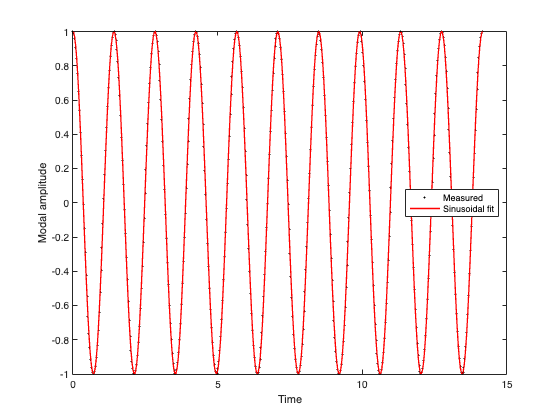

 %plot another curve, dashed. do a separate plot of the error
 plot(t_pts,a,'k.',t_pts,fit.values,'r-','LineWidth',1.3)
 xlabel('Time'); ylabel('Modal amplitude')
 legend('Measured','Sinusoidal fit','Location','best')

Fitting Residual

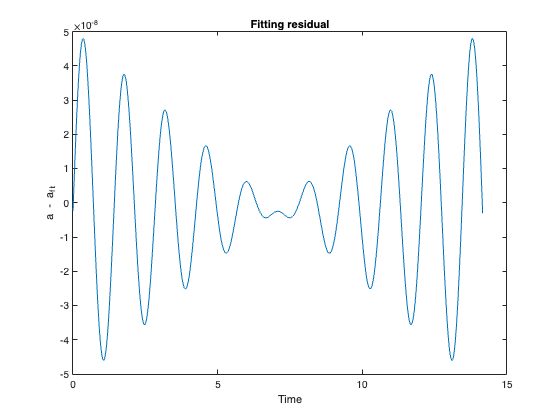

figure;
plot(t_pts,a-fit.values);
xlabel('Time');
ylabel('a - a_{fit}');
title('Fitting residual');

Temporal Spectrum

dt_actual = t_pts(2)-t_pts(1);
N = numel(a);

aCentered = a-mean(a);
A = fft(aCentered);

freq = (0:N-1)'/(N*dt_actual);
omega = 2*pi*freq;

Npositive = floor(N/2)+1;
[~,idx] = max(abs(A(2:Npositive)));
idx = idx+1;

omegaFFT = omega(idx);

fprintf('FFT frequency estimate: %.6f\n', omegaFFT);

FFT frequency estimate: 4.427702


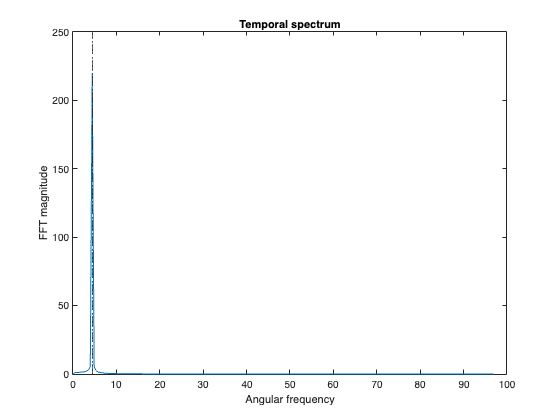


figure;
plot(omega(1:Npositive),abs(A(1:Npositive)));
xline(omega_pred,'--');
xline(omega_meas,':');
xlabel('Angular frequency');
ylabel('FFT magnitude');
title('Temporal spectrum');

error calculations

Texact = 2*pi/omega_exact;
Tpred  = 2*pi/omega_pred;
Tmeas  = 2*pi/omega_meas;

validationError = abs(omega_meas-omega_pred)/abs(omega_pred);

predictedDispersion = (omega_pred-omega_exact)/omega_exact;
measuredDispersion  = (omega_meas-omega_exact)/omega_exact;

fprintf('Exact frequency: %.6f\n', omega_exact);

Exact frequency: 4.442883


fprintf('Predicted frequency: %.6f\n', omega_pred);

Predicted frequency: 4.438573


fprintf('Measured frequency: %.6f\n', omega_meas);

Measured frequency: 4.438573


fprintf('Validation error: %.4f%%\n', 100*validationError);

Validation error: 0.0000%


fprintf('Predicted dispersion: %.4f%%\n', 100*predictedDispersion);

Predicted dispersion: -0.0970%


fprintf('Measured dispersion: %.4f%%\n', 100*measuredDispersion);

Measured dispersion: -0.0970%


Testing Errors

%list of grid resolutions i want to test
N_lambda_values = [12 14 16 18 20];

validationError = zeros(size(N_lambda_values));
measuredDispersion = zeros(size(N_lambda_values));
predictedDispersion = zeros(size(N_lambda_values));

for j = 1:length(N_lambda_values)
    N_lambda = N_lambda_values(j);

    % Run your simulation using this N_lambda.
    % Recalculate omega_meas, omega_pred, and omega_exact.

    validationError(j) = abs(omega_meas - omega_pred) ...
                         / abs(omega_pred);

    measuredDispersion(j) = (omega_meas - omega_exact) ...
                            / omega_exact;

    predictedDispersion(j) = (omega_pred - omega_exact) ...
                             / omega_exact;
end

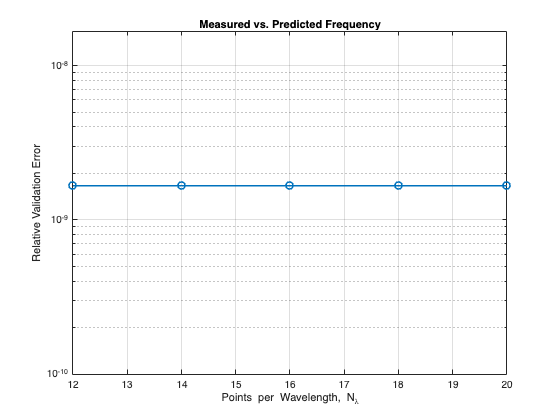

figure;
semilogy(N_lambda_values, validationError, 'o-', ...
    'LineWidth', 1.5, 'MarkerSize', 7);

xlabel('Points per Wavelength, N_\lambda');
ylabel('Relative Validation Error');
title('Measured vs. Predicted Frequency');
grid on;

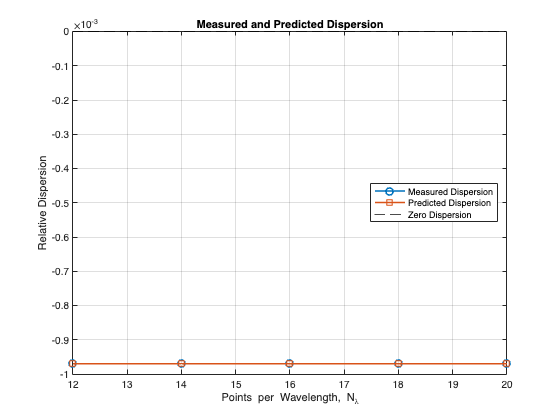

figure;
plot(N_lambda_values, measuredDispersion, 'o-', ...
    'LineWidth', 1.5, 'MarkerSize', 7);

hold on;
plot(N_lambda_values, predictedDispersion, 's-', ...
    'LineWidth', 1.5, 'MarkerSize', 7);
yline(0, '--k', 'Exact Frequency');
hold off;

xlabel('Points per Wavelength, N_\lambda');
ylabel('Relative Dispersion');
title('Measured and Predicted Dispersion');
legend('Measured Dispersion', 'Predicted Dispersion', ...
    'Zero Dispersion', 'Location', 'best');
grid on;

function result = fitModalFrequency(t,a,omega_pred)
 % Fit a(t) = B*cos(omega*t) + C*sin(omega*t) + D.
     t = t(:);
     a = a(:);
     valid = isfinite(t) & isfinite(a);
     t = t(valid);
     a = a(valid);
     % Shift the time origin to improve conditioning.
     tau = t - t(1);
     objective = @(omega) fitResidual(omega,tau,a);
     % A moderate bracket prevents selection of an unrelated minimum.
     omegaLower = 0.8*omega_pred;
     omegaUpper = 1.2*omega_pred;
     options = optimset('TolX',1e-12,'Display','iter');
     omegaMeas = fminbnd(objective,omegaLower,omegaUpper,options);
     X = [cos(omegaMeas*tau), ...
          sin(omegaMeas*tau), ...
          ones(size(tau))];
     q = X \ a;
     aFit = X*q;
     B = q(1);
     C = q(2);
     D = q(3);
     result.omega = omegaMeas;
     result.amplitude = hypot(B,C);
     result.phase = atan2(-C,B);
     result.offset = D;
     result.values = aFit;
     result.relResidual = norm(a-aFit)/norm(a);
end
 function value = fitResidual(omega,t,a)
     X = [cos(omega*t), sin(omega*t), ones(size(t))];
     q = X \ a;
     r = a-X*q;
     value = r'*r;
 end